# IQ Demodulator E Function 12-bit

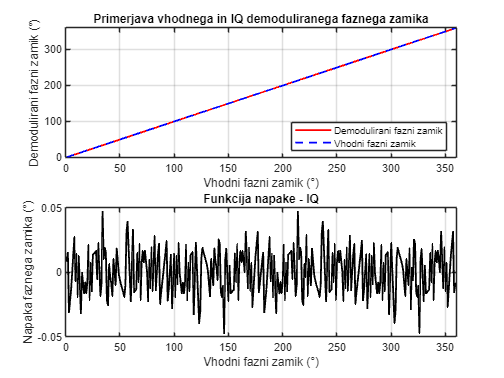

clc
clear all
close all

% Parametri
FREQUENCY = 10e6;           % Frekvenca signala
SAMPLE_RATE = 62.5e6;       % Frekvenca vzorčenja
SAMPLE_COUNT = 4096;        % Število vzorcev
WINDOW_SIZE = 100;          % Velikost nizko-pasovnega filtra
PHASE_SHIFT_DEG = 0:1:359;  % Razpon faznih zamikov v stopinjah
BIT_DEPTH = 12;             % Nastavljiva bitna globina

% Izpeljani parametri
t = (0:SAMPLE_COUNT-1) / SAMPLE_RATE;
PHASE_SHIFT = deg2rad(PHASE_SHIFT_DEG);
num_shifts = length(PHASE_SHIFT);

% Pretvorba bitne globine v kvantizacijski faktor
QUANTIZATION_LEVELS = 2^(BIT_DEPTH-1) - 1;

% Referenčna signala z nastavljivo kvantizacijo
lo = round(sin(2*pi*FREQUENCY*t) * QUANTIZATION_LEVELS) / QUANTIZATION_LEVELS;          % Osnovni
lo90 = round(sin(2*pi*FREQUENCY*t - pi/2) * QUANTIZATION_LEVELS) / QUANTIZATION_LEVELS; % V kvadraturi

% Inicializacija rezultatov
demodulated_phases = zeros(1, num_shifts);  % Shranjevanje demoduliranih faz
phase_errors = zeros(1, num_shifts);        % Shranjevanje napak faz

% Iteracija čez vse faze
for idx = 1:num_shifts
    % Generacija vhodnega signala z nastavljivo kvantizacijo
    in_test = round(sin(2*pi*FREQUENCY*t + PHASE_SHIFT(idx)) * QUANTIZATION_LEVELS) / QUANTIZATION_LEVELS;
    
    % Demodulacija v obliki korelacije z nastavljivo kvantizacijo
    I_hf = round(in_test .* lo * QUANTIZATION_LEVELS) / QUANTIZATION_LEVELS;
    Q_hf = round(in_test .* lo90 * QUANTIZATION_LEVELS) / QUANTIZATION_LEVELS;
    
    % Nizkoprepustni filter
    b = (1/WINDOW_SIZE) * ones(1, WINDOW_SIZE);
    a = 1;
    I_filtered = filter(b, a, I_hf);
    Q_filtered = filter(b, a, Q_hf);
    
    % Zadnja točka ustaljenega stanja z nastavljivo kvantizacijo
    final_I = round(I_filtered(end) * QUANTIZATION_LEVELS) / QUANTIZATION_LEVELS;
    final_Q = round(Q_filtered(end) * QUANTIZATION_LEVELS) / QUANTIZATION_LEVELS;
    
    % Izračun faze z nastavljivo preciznostjo
    demodulated_phases(idx) = round(360 - mod(atan2d(final_Q, final_I), 360), BIT_DEPTH);
    
    % Izračun napake faze
    phase_errors(idx) = demodulated_phases(idx) - PHASE_SHIFT_DEG(idx);
end

% Izris rezultatov
figure;
subplot(2, 1, 1);
plot(PHASE_SHIFT_DEG(2:end), demodulated_phases(2:end), 'r', 'LineWidth', 1.5);
hold on;
plot(PHASE_SHIFT_DEG(2:end), PHASE_SHIFT_DEG(2:end), 'b--', 'LineWidth', 1.5);
title('Primerjava vhodnega in IQ demoduliranega faznega zamika');
xlabel('Vhodni fazni zamik (°)');
ylabel('Demodulirani fazni zamik (°)');
legend({'Demodulirani fazni zamik', 'Vhodni fazni zamik'}, 'Location', 'southeast');
ylim([0 360])
xlim([0 360])
grid on;

subplot(2, 1, 2);
plot(PHASE_SHIFT_DEG(2:end), phase_errors(2:end), 'k', 'LineWidth', 1.5);
title('Funkcija napake - IQ');
xlabel('Vhodni fazni zamik (°)');
ylabel('Napaka faznega zamika (°)');
xlim([0 360])
grid on;


% Izpis napak
fprintf('Največja napaka faze: %.2f stopinj\n', max(abs(phase_errors(2:end))));

Največja napaka faze: 0.05 stopinj


fprintf('Povprečna absolutna napaka faze: %.2f stopinj\n', mean(abs(phase_errors(2:end))));

Povprečna absolutna napaka faze: 0.01 stopinj
